# Differentiation

**The differentation of a function is obtained by:**

syms x
diff(sin(x),x)

$$ans = \cos\left(x\right)$$

syms x a
f=exp(x^2+a^2)

$$f = {\mathrm{e}}^{a^{2}+x^{2}}$$

diff(f,x)

$$ans = 2\,x\,{\mathrm{e}}^{a^{2}+x^{2}}$$

diff(y,x) % or using diff(f,x,2)

$$ans = 2\,{\mathrm{e}}^{a^{2}+x^{2}}+4\,x^{2}\,{\mathrm{e}}^{a^{2}+x^{2}}$$

diff(sin(x^2),x,5)

$$ans = 32\,x^{5}\,\cos\left(x^{2}\right)-120\,x\,\cos\left(x^{2}\right)+160\,x^{3}\,\sin\left(x^{2}\right)$$

## Partial Differentiation

Q. $z=\mathrm{sin}\left(x\right)\mathrm{cos}\left(y\right)$ then find$\;\frac{\partial }{\partial x}\frac{\partial }{\partial y}z$

syms x y
z = sin(x)*cos(y);
diff(z,x,y)

$$ans = -\cos\left(x\right)\,\sin\left(y\right)$$

Q. Find $\frac{\textrm{d}}{\textrm{d}x}\left(\frac{{\left(x^2 +1\right)}^4 }{e^x }\right)$ and evaluate it a t x=1

syms x
z = ((x^2+1)^4)/exp(x)

$$z = {\mathrm{e}}^{-x}\,{\left(x^{2}+1\right)}^{4}$$

f(x) = diff(z,x);
f(1)

$$ans = 48\,{\mathrm{e}}^{-1}$$

Q. Plot the second derivative of $\frac{x^4 }{\left(1+x^2 \right)}\;$for $-5\le x\le 5$.

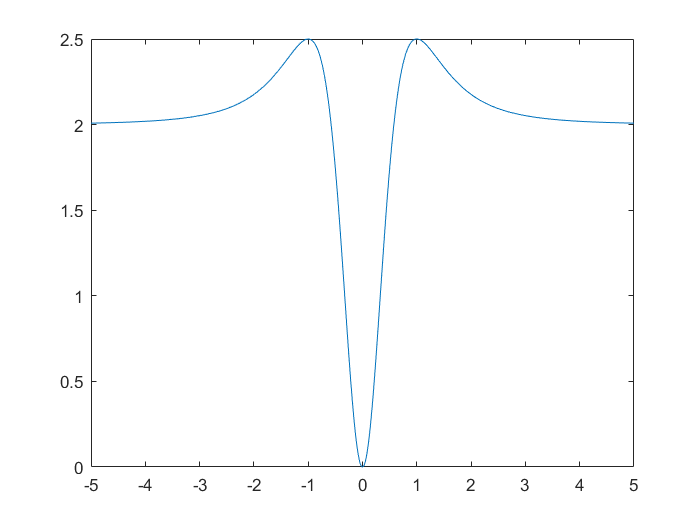

syms x
f(x)=x^4/(1+x^2);
g(x)=diff(f(x),2);
fplot(g(x))
xlim([-5 5])

Q. Given $y=x^3 -6x^2 +9x-2$, find the (x,y) coordinates of the stationary point.

syms x
f(x) = x^3-6*x^2+9*x-2;
g(x) = diff(f(x),x) == 0;
sol = solve(g(x))

$$sol = \left(\begin{array}{c} 1\\ 3 \end{array}\right)$$

f(sol)

$$ans = \left(\begin{array}{c} 2\\ -2 \end{array}\right)$$

Q. Given $y=12x^5 -15x^4 +20x^3 -300x^2 +2$. Find the coordinates of any stationary points. Plot y such that it covers all the stationary points.

syms x
f(x) = 12*x^5-15*x^4+20*x^3-300*x^2+2;
g(x) = diff(f(x),2)==0;
xvector = vpasolve(g(x)) %Instead of solve(), use vpasolve() to obtain the values of x.

$$xvector = \left(\begin{array}{c} 1.5123845866063535322183258878091\\ -0.38119229330317676610916294390455-1.2278888929280086033725403095487\,\mathrm{i}\\ -0.38119229330317676610916294390455+1.2278888929280086033725403095487\,\mathrm{i} \end{array}\right)$$

yvector = f(xvector)

$$yvector = \left(\begin{array}{c} -598.53353802241234907110860207493\\ 387.33317526120617453555430103746-219.02430608761541138074831473991\,\mathrm{i}\\ 387.33317526120617453555430103746+219.02430608761541138074831473991\,\mathrm{i} \end{array}\right)$$

# Integration

**The integration of a function can be obtained by:**

syms a x
f(x) = sin(x)

$$f(x) = \sin\left(x\right)$$

g(x) = int(f(x),x)

$$g(x) = -\cos\left(x\right)$$

h(x) = x*exp((a*x^2))

$$h(x) = x\,{\mathrm{e}}^{a\,x^{2}}$$

i(x) = int(h(x),x)

$$i(x) = \frac{{\mathrm{e}}^{a\,x^{2}}}{2\,a}$$

j(x) = 1/sqrt(a-x)

$$j(x) = \frac{1}{\sqrt{a-x}}$$

k(x) = int(j(x),x,[0 a])

$$k(x) = 2\,\sqrt{a}$$

**For numerical integration, when f(x) is difficult to evaluate:**

l(x) = vpaintegral(j(x),x,[0 a])

$$l(x) = \text{vpaintegral}\left(\frac{1}{\sqrt{a-x}},x,0,a\right)$$

Q. To evaluate $\int_{-1}^2 \int_1^3 \mathrm{xydxdy}$

syms x y
f(x,y)= x*y;
vpaintegral(vpaintegral(f(x,y),x,[1 3]),y,[-1 2])

$$ans = 6.0$$

# Summations

## To evaluate summations of type:

                
$$\sum_a^b f\left(x\right)$$


syms x
symsum(f(x),[a b]);

Q. Evaluate the following:


$$\sum_{r=1}^{10} r^2 +3r-2$$


syms r
f(r)= r^2+3*r-2;
symsum(f(r),[1 10])

$$ans = 530$$

Q. Evaluate

 
$$\sum_0^{\infty } \frac{1}{k!}$$


syms x
f(x) = 1/factorial(x);
symsum(f(x), [0 inf])

$$ans = \mathrm{e}$$

Q. Evaluate:


$$\sum_{k=0}^{n-1} a^k$$


syms x a n
symsum(a^x,[0 n-1])

$$ans = \left\{ \begin{array}{cl} n & \text{ if }a=1\\ \frac{a^{n}-1}{a-1} & \text{ if }a\neq 1 \end{array}\right.$$

Q. Verify the following:


$$\sum_{n=-20}^{20} \sum_{m=-10}^{\mathrm{10}} \frac{1}{n^2 +\mathrm{ln}\left(22+m\right)}$$


syms m n
symsum(symsum(1/(n^2+log(22+m)), m,[-10 10]), n, [-20 20])

# Limits

**To evaluate limits using Symbolic Math Toolbox:**

                                
$$\lim_{x\to 0} \frac{\mathrm{sin}\left(x\right)}{x}$$


syms x
limit(sin(x)/x,x,0)

$$ans = 1$$

**To obtain the left and right limits:**

limit(sin(x)/x,x,0,'right')

$$ans = 1$$

limit(sin(x)/x,x,0,'left')

$$ans = 1$$

Q. Evaluate:


$$\lim_{x\to 0} \frac{\mathrm{tan}\left(x\right)-x}{x-\mathrm{sin}\left(x\right)}$$


syms x
f(x) = (tan(x)-x)/(x-sin(x));
limit(f(x),x,0)

$$ans = 2$$

Q. Find the value of K, if f(x) is continous:


$$f\left(x\right)=\left\lbrace \begin{array}{cc}
\mathrm{kx}+7 & x\ge 2\\
x^2 +19 & x<2
\end{array}\right.$$


syms x k 
% Use limits
LHL = limit(k*x+7,x,2,'left');
RHL = limit(x^2+19,x,2,'right');
value = solve(LHL==RHL)

$$value = 8$$